# Experimental Fluids Lab #1

## Calibration

% % Import Calibration Data (PC)
% cdir = 'C:\Users\dlawson6\Desktop\Raw Lab Data\Experimental Methods Lab #1\';
% LISTING = dir([cdir,'Calibration\test*.mat']);
% [~,idx] = sort(cellfun(@(x) x,{LISTING(:).date},'UniformOutput',false));
% LISTING=LISTING(idx);
% for hh =1:length(LISTING)
%     [~,filelead] = fileparts(LISTING(hh).name);
%     load([cdir,'Calibration\',filelead,'.mat'])
%     setra(hh) = mean(timeseries_data(:,1))'; % pressure xdcr voltages
%     cta(hh) = mean(timeseries_data(:,2))';% anemometer voltages
% end

% % Import Calibration Data (Mac OS)
cdir = '/Users/dan/Desktop/Lab Data/Experimental Fluids Lab #1/';
LISTING = dir([cdir,'Calibration/test*.mat']);
[~,idx] = sort(cellfun(@(x) x,{LISTING(:).date},'UniformOutput',false));
LISTING=LISTING(idx);
for hh =1:length(LISTING)
    [~,filelead] = fileparts(LISTING(hh).name);
    load([cdir,'Calibration/',filelead,'.mat'])
    setra(hh) = mean(timeseries_data(:,1))'; % pressure xdcr voltages
    cta(hh) = mean(timeseries_data(:,2))';% anemometer voltages
end


% Conditions and Initialization

freq_f =  [0, 6, 10, 15, 20, 25, 30, 34, 37.5]; % fan frequency (Hz)
T_s = 10; % time (s)
freq_s = 20000; % Sample Frequency (Hz)
Cal_factor = 67.82; % Pressure Transducer Calibration: 67.82 [Pa/V]
Pvol_cal = abs(setra - setra(1)); % Zeroed Pressure transducer voltages for calibration (V)
P_Pitot = Cal_factor * Pvol_cal; % Pitot tube pressure readings (Pa)

P_amb1 = 1000.5 * 100; % Ambient pressure at the start of lab, convert from millibar -> Pa, (Pa)
P_amb2 = 1000.5 * 100; % Ambient pressure at the end of lab (same as start), convert from millibar -> Pa, (Pa)
T_amb1 = 23.8 + 273; % Ambient Temperature at start of lab, convert from centigrade -> Kelvin (K)
T_amb2 = 23.2 + 273; % Ambient Temperature at end of lab, convert from centigrade -> Kelvin (K)
R = 287; % Gas constant for air (J / Kg *K)

% Convert differntial pressure readings into velocities using Bernoulli's

rho1 = P_amb1 / (R * T_amb1); % Incompressible air density at start of lab (kg/m^)

for ii = 1:length(P_Pitot)

U_pitot(ii) = sqrt(2 * abs(P_Pitot(ii)) / rho1); % Air velocities from pitot tube measuremnt (m/s)

end

% Determine the total relative errors in velocity calibration from
% pressure/temperature sensors and pressure transducer

% Input and calculate device acccuracies and sources of uncertainty 

acc_P_amb = 4 * 100; % +/- Accuracy of ambient pressure measurement, converts from mBar to Pa (Pa)
acc_T_amb = 0.4; % +/- Accuracy of ambient temperature measurement (K)
acc_Tran = (0.5/100) * 550; % Accuracy of pressure transducer, converted from relative to Pa via Full-Scale (Pa)

res_P_amb = 1 * 100; % Resolution of ambient pressure measurement, converts from mBar to Pa (Pa)
res_T_amb = 0.1; % Resolution of ambient temperature measurement (K)

drift_T_amb = (T_amb1 - T_amb2) / 2; % drift error of initial and end ambient temperature (K)

% Calculate relative errors
rho_bar = ((P_amb1 / (R * T_amb1)) + (P_amb2 / (R * T_amb2))) / 2; % Mean of air density from start and end of lab

err_P_amb = sqrt(acc_P_amb^2 + res_P_amb^2); % Absolute error for ambient pressure measurement (Pa)
err_T_amb = sqrt(acc_T_amb^2 + res_T_amb^2 + drift_T_amb^2); % Absolute error for ambient temperature measurement (K)
err_Tran = acc_Tran; % Absolute error of pressure transducer, equal to its accuracy (Pa)
err_rho = sqrt((err_T_amb / (0.5 * (T_amb1 + T_amb2)))^2 + (err_P_amb / (0.5 * (P_amb1 + P_amb2)))^2); % Absolute error of air density, (Kg / m^3)

err_U_pitot = [];


% Calculate and display relative errors of each Pitot Velocity Measurement

for j = 1:length(U_pitot)

    err_U_pitot(j) = 100 * sqrt((0.5 * (err_Tran / P_Pitot(j)))^2 + (0.5 * (err_rho / rho_bar))^2);

end

% ****Insert Table figure here that dispalys each velocity and its error

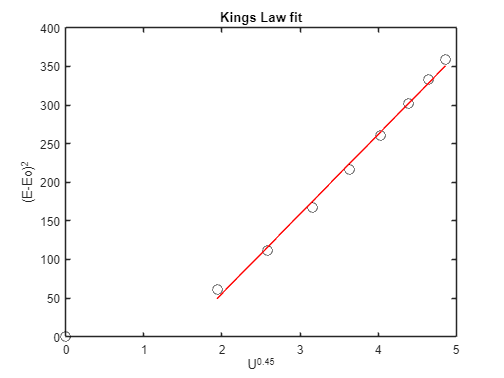

% Find the A and B constants in King's Law

Avol_cal = cta;
Y = [];
X = [];
n = 0.45;

for jj = 1:length(Avol_cal)

Y(jj) = (Avol_cal(jj) - Avol_cal(1))^2;
X(jj) = U_pitot(jj)^n;

end

y = Y(2:end); % Create data vectors excluding data first point
x = X(2:end);

p1 = polyfit(x, y, 1); % Use polyfit/val to fit the data with a 1st order polynomial
y_fit1 = polyval(p1, x);
y_cfit1 = polyval(p1, x);

figure % Create plot of the fitted data excluding first data point
plot(X,Y,'ko', MarkerSize=8)
hold on
plot(x, y_fit1, 'r-');
title('Kings Law fit')
xlabel('U^0.45')
ylabel('(E-Eo)^2')


A = p1(2) % A and B constants as found by polyfit of adjusted data sets

A = -150.5832

B = p1(1)

B = 103.1440

## Data Analysis

% Import Experimental Data

% Import Lab Data
cdir = 'C:\Users\dlawson6\Desktop\Raw Lab Data\Experimental Methods Lab #1\'; % change between OS's (no " or _ )';
LISTING = dir([cdir,'Boundary Layer\test*.mat']);
[~,idx] = sort(cellfun(@(x) x,{LISTING(:).date},'UniformOutput',false));
LISTING=LISTING(idx);
for hh =1:length(LISTING)
    [~,filelead] = fileparts(LISTING(hh).name);
    load([cdir,'Boundary Layer\',filelead,'.mat'])
    E(:,hh)=timeseries_data(:,2)'; % anemometer voltages
end

y = readmatrix([cdir,'step_list']);y=y(:,4);

% Compute mean velocity profile of the Boundary Layer

for i = 1:height(E)
    for iii = 1:width(E)
    
    U_BL(i) = ((((E(i,iii) - E(1,iii))^2 - A)) / B)^n;
    
    end
end